2.1 

delete(gcp("nocreate")); %added this to get rid of weird erro
X =randi([1 10],100);
c = parcluster;
p = c.parpool(4);

Starting parallel pool (parpool) using the 'Processes' profile ...
Parallel pool using the 'Processes' profile is shutting down.




H = 0;
D = distributed(X);
spmd
	%fprintf('Worker %d says Hello World!\n', spmdIndex);
    for z = spmdIndex:25+spmdIndex
        if D(z) == 1
            H = H+1;
        end
    end
end
GResult = gather(H);
finalResult = 0;
GResult = cell2mat(GResult);
for t = 1:length(GResult)
    finalResult = finalResult + GResult(1,t);
end
disp(finalResult);
p.delete;

I just did some testing one this with diffenent number of workers and plotted this graph as proof that we expiremented to find the fastest option

workers = [1,2,4,5];
runtimes = [1.243139e+04, 1.204113e+04,1.490712e+04,1.816805e+04];
plot(workers,runtimes)
xlabel("Number of workers in the pool");
ylabel("Runtime in ms");
title("Graph of runtime[ms] vs number of workers")

2.2

Don't run this with 10 000 samples  - it will take more than 10 minutes, just take it out or change the value to see how it works

%This loops through each item in a colum and will sort each column from
%lowwest to highest
%2.2b

sampleSizes = [100, 200, 500, 1000, 10000];
runtime1s =zeros(1,size(sampleSizes,2));
runtime2s = zeros(1,size(sampleSizes,2));


for i = 1:size(sampleSizes,2)
    [runtime1s(i), unsortedM] = myBubbleSort(sampleSizes(i));
    tic();
    quickSortedMatric = sort(unsortedM);
    runtime2s(i) = toc()*1000;
end
disp(runtime1s)
disp(runtime2s)

speedUp = runtime1s./runtime2s
figure = plot(sampleSizes,speedUp);

% figure
% plot(sampleSizes,runtime1s)
% hold on
% plot(sampleSizes,runtime2s)
% legend('unoptimised','optimised')
% title("Speeds of sorting vs sample size")
% hold off






%This function sorts an array and returns the time taken to do so
%It uses the bubble sort algorym and takes in N, size of a square matrix
%It returns the unsorted matrix such that the exact same matrix can be
%sorted with the built in sort function so accurate preformance data
%can be analysed 
% had to move this to the buttom of the scrip cause matlab said so

2.3

for j = [100 500 5000]
	X=rand(100,100);
	c = parcluster;
	p = c.parpool(4)
    %D = distributed(X);
    tstart = tic;
	spmd
		%fprintf('Worker %d says Hello World!\n', spmdIndex);
        for l = 1:j
		    sort(X,1);%spmdIndex
        end     
end
	%finalResult = gather(D);


    tend = toc(tstart);
    disp(strcat("It took: ", num2str(tend*1000), " ms to run"));
    p.delete;
end

2.3 Thomas attempt

Maybe I don't understand the question, but I think we are ment to compared the implicit vs explicit speed up. The implicit speed up from the sort function sorting all the columns in a square matrix comes from how it sorts each row. To test explict parralelesmi (or however I am ment to spell that word) comes from induvidually sorting each row, then putting it all back together. I used parsfor, but you could definetly use spmd and then gather all the rows back together. Your spmd and for loop just sorts it in one go multilple times. While this should get roughly the right values we still need to compare accurately so I have done this below. 

Basically just check my logic to make sure that Im not going crazy

Test for 2.3 - Thomas additon


%deletes the parralell proccess so we 
%can restart it (below)
runtimeUO = zeros(3,1);
runtimeO = zeros(3,1);
samplesSizes = [50,100,200,500,1000,5000];
c = parcluster;
p = c.parpool(6);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


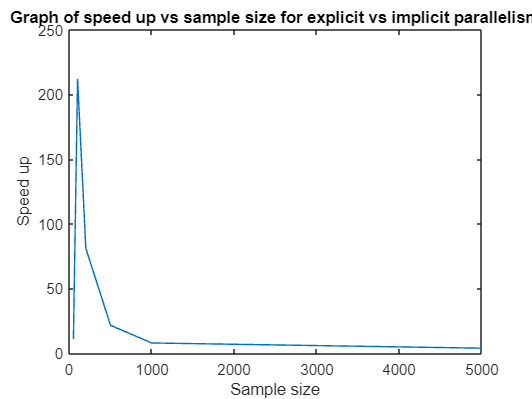

%test for all the sample sizes
for i = 1:size(samplesSizes,2)
    X =randi([1 10],samplesSizes(i));
    tic()
    sort(X,1);
    runtimeO(i) = toc()*1000;
    %calls the function and gets the runtime
    runtimeUO(i) = explicitTest(X);
end

%calculates the speedup
speedUp = runtimeUO./runtimeO;
%plots the speed up
plot(samplesSizes,speedUp)
xlabel("Sample size")
ylabel("Speed up")
title("Graph of speed up vs sample size for explicit vs implicit parallelism")

p.delete

Parallel pool using the 'Processes' profile is shutting down.


Function for 2.3 to explicitly test parralellism

function runtime= explicitTest(M)
tic();
   parfor( i =1:size(M,1))
       M(:,i) = sort(M(:,i));
   end
runtime = toc()*1000;

end

other functions

%This function sorts an array and returns the time taken to do so
%It uses the bubble sort algorym and takes in N, size of a square matrix
%It returns the unsorted matrix such that the exact same matrix can be
%sorted with the built in sort function so accurate preformance data
%can be analysed had to move this to the buttom of the scrip cause matlab
%said so
function [time, unsortedMatrix] = myBubbleSort(N)
    
    matrix = rand(N);
    unsortedMatrix = matrix; 
    % need this to make the sort data the same for a fair test
    n = size(matrix,1); %row size
    m = size(matrix,2); %column size
    tic();
    for k = 1:m % the column loop
        for i = 1:n %outer bubble sort
            for j = 1:(n - i) %inner bubble sort
                if matrix(j,k) > matrix(j + 1,k)
                    % Swap elements
                    temp = matrix(j,k);
                    matrix(j,k) = matrix(j + 1,k);
                    matrix(j + 1,k) = temp;
                end
            end
        end
    end
    time = toc()*1000;
end